M = 1000;    % Mass of crane 
m1 = 100;    % Mass of load 1 
m2 = 100;    % Mass of load 2 
l1 = 20;     % Length of cable 1 
l2 = 10;     % Length of cable 2 
g = 9.81;    % Gravitational acceleration 

% Linearized System Matrices
A = [0 1 0 0 0 0;
     0 0 -(m1*g)/M 0 -(m2*g)/M 0;
     0 0 0 1 0 0;
     0 0 -(g*(M + m1))/(l1*M) 0 -(m2*g)/(l1*M) 0;
     0 0 0 0 0 1;
     0 0 -(m1*g)/(l2*M) 0 -(g*(M + m2))/(l2*M) 0];

B = [0; 1/M; 0; 1/(l1*M); 0; 1/(l2*M)];


% LQR Design
Q = diag([100, 10, 100, 10, 100, 10]);  
R = 0.01;                              
[K, ~, eig_cl] = lqr(A, B, Q, R);      

disp('LQR Gain Matrix (K):');

LQR Gain Matrix (K):


disp(K);

  100.0000  488.4994  -76.9232 -563.0424  -39.2419 -296.8296



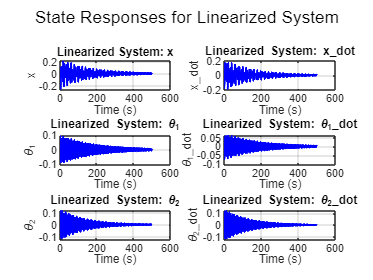


% Linearized System with LQR Controller
sys_cl = ss(A - B*K, [], eye(6), []); % Closed-loop system

% Initial Conditions
x0 = [0.1; 0; 0.1; 0; 0.1; 0]; % 
t = linspace(0, 500, 10000); % 
[~, t, x_lin] = initial(sys_cl, x0, t);

% Nonlinear System Dynamics Function
function dx = nonlinear_dynamics(t, x, u)
    M = 1000; m1 = 100; m2 = 100; l1 = 20; l2 = 10; g = 9.81;
    x1 = x(1); x2 = x(2); theta1 = x(3); theta1_dot = x(4); theta2 = x(5); theta2_dot = x(6);
    x_ddot = (u - m1*l1*(theta1_dot^2)*sin(theta1) - m2*l2*(theta2_dot^2)*sin(theta2) ...
              - m1*g*sin(theta1)*cos(theta1) - m2*g*sin(theta2)*cos(theta2)) / ...
              (M + m1 + m2 - m1*(cos(theta1)^2) - m2*(cos(theta2)^2));
    theta1_ddot = (x_ddot*cos(theta1) - g*sin(theta1)) / l1;
    theta2_ddot = (x_ddot*cos(theta2) - g*sin(theta2)) / l2;
    dx = [x2; x_ddot; theta1_dot; theta1_ddot; theta2_dot; theta2_ddot];
end

% Nonlinear System with LQR Controller
[t_nl, x_nl] = ode45(@(t, x) nonlinear_dynamics(t, x, -K*x), [0, 2000], x0);

% Linearized System Responses plots
figure;
state_labels = {'x', 'x\_dot', '\theta_1', '\theta_1\_dot', '\theta_2', '\theta_2\_dot'};
for i = 1:6
    subplot(3, 2, i);
    plot(t, x_lin(:, i), 'b', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel(state_labels{i});
    title(['Linearized System: ', state_labels{i}]);
    grid on;
end
sgtitle('State Responses for Linearized System');

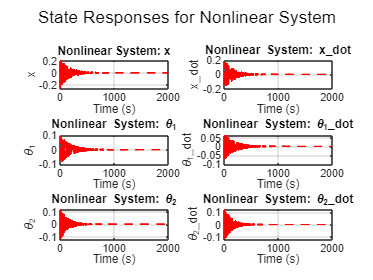


% Nonlinear System Responses plots
figure;
for i = 1:6
    subplot(3, 2, i);
    plot(t_nl, x_nl(:, i), 'r--', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel(state_labels{i});
    title(['Nonlinear System: ', state_labels{i}]);
    grid on;
end
sgtitle('State Responses for Nonlinear System');